# Machine Learning Online Class

## Initialization

## ================ Part 1: Feature Normalization ================

## Clear and Close Figures

clear ; close all; clc

fprintf('Loading data ...\n');

Loading data ...


## Load Data

data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


%pause;

% Scale features and set them to zero mean
fprintf('Normalizing Features ...\n');

Normalizing Features ...



[X mu sigma] = featureNormalize(X);

% Add intercept term to X
X = [ones(m, 1) X]

X =     1.0000    0.1300   -0.2237
    1.0000   -0.5042   -0.2237
    1.0000    0.5025   -0.2237
    1.0000   -0.7357   -1.5378
    1.0000    1.2575    1.0904
    1.0000   -0.0197    1.0904
    1.0000   -0.5872   -0.2237
    1.0000   -0.7219   -0.2237
    1.0000   -0.7810   -0.2237
    1.0000   -0.6376   -0.2237


## ================ Part 2: Gradient Descent ================

% ====================== YOUR CODE HERE ======================
% Instructions: We have provided you with the following starter
%               code that runs gradient descent with a particular
%               learning rate (alpha). 
%
%               Your task is to first make sure that your functions - 
%               computeCost and gradientDescent already work with 
%               this starter code and support multiple variables.
%
%               After that, try running gradient descent with 
%               different values of alpha and see which one gives
%               you the best result.
%
%               Finally, you should complete the code at the end
%               to predict the price of a 1650 sq-ft, 3 br house.
%
% Hint: By using the 'hold on' command, you can plot multiple
%       graphs on the same figure.
%
% Hint: At prediction, make sure you do the same feature normalization.
%

fprintf('Running gradient descent ...\n');

Running gradient descent ...


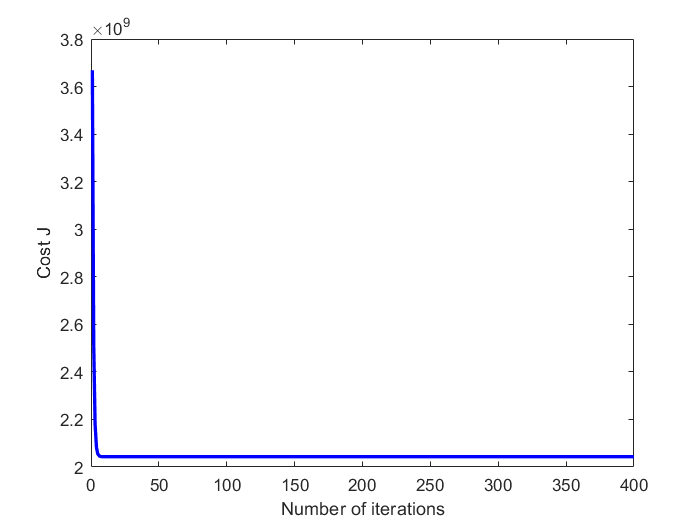

% Choose some alpha value
alpha = 1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');


% % Choose some alpha value
% alpha = [0.01 0.03 0.1 0.3 1];
% color = ['-r', '-b', '-k', '-m', '-c'];
% num_iters = 400;
% 
% % Plot the convergence graph
% figure;
% xlabel('Number of iterations');
% ylabel('Cost J');
% 
% % Init Theta and Run Gradient Descent
% alpha_num =length(alpha);
% theta = zeros(3, alpha_num);
% J_history = zeros(alpha_num, num_iters);
% 
% for i = 1:alpha_num
%     
%     
%     [theta(:,i), J_history(i,:)] = gradientDescentMulti(X, y, theta(:,i), alpha(i), num_iters);
%     
%     
%     plot(1:numel(J_history(i,:)), J_history(i,:), color(i), 'LineWidth', 2);
%     hold on
% end
% hold off
% legend (num2str(alpha(1)), num2str(alpha(2)), num2str(alpha(3)), num2str(alpha(4)), num2str(alpha(5)));


% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');

Theta computed from gradient descent: 


fprintf(' %f \n', theta);

 340412.659574 
 110631.050279 
 -6649.474271 


fprintf('\n');


% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.
x_new = [1650 3];
x_new_norm = (x_new- mu)./sigma;
x_new_norm = [1, x_new_norm];
price = x_new_norm*theta; % You should change this


% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using gradient descent):\n $%f\n'], price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $293081.464335



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


%pause;

## ================ Part 3: Normal Equations ================

fprintf('Solving with normal equations...\n');

Solving with normal equations...



% ====================== YOUR CODE HERE ======================
% Instructions: The following code computes the closed form 
%               solution for linear regression using the normal
%               equations. You should complete the code in 
%               normalEqn.m
%
%               After doing so, you should complete this code 
%               to predict the price of a 1650 sq-ft, 3 br house.
%

## Load Data

data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations: \n');

Theta computed from the normal equations: 


fprintf(' %f \n', theta);

 89597.909544 
 139.210674 
 -8738.019113 


fprintf('\n');



% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
x = [1650 3];
x = [1, x];
price = x*theta; % You should change this


% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
         '(using normal equations):\n $%f\n'], price);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335
